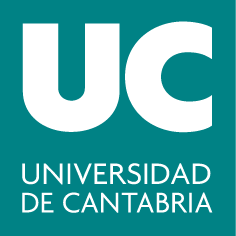

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 3: Integrales dobles en polares e integrales triples sobre cajas**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Manejar las coordenadas polares y dibujar con MATLAB curvas dadas por una ecuación polar. 

- Calcular integrales dobles de forma simbólica, utilizando coordenadas polares.

- Calcular integrales triples de forma aproximada, mediante sumas de Riemann. 

- Calcular integrales triples de forma exacta, con cálculo simbólico.

### Resumen teórico

#### Integrales dobles con cambio a polares

Las fórmulas del cambio son: $x=rcos\theta$ , $y=rsen\theta$ y el diferencial de área $dA=r drd\theta$ incluye el Jacobiano ($r$), resultando la integral:


$$\int\int_{R}f(x,y)dxdy=\int\int_{S}f(rcos\theta, rsen\theta) r dr d\theta$$


#### Suma triple de Riemann

Llamamos suma de Riemann de la función $f(x,y,z)$ definida en la caja $H$ para la partición $\lbrace H_{k}\rbrace_{k=1}^{p}$ a la suma:


$$\displaystyle  \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k} $$


donde $(x_{k},y_{k}, z_{k})$ es un punto cualquiera tomado en la subcaja $$H_{k}$$ y $\Delta V_{k}$es el volumen de  $$H_{k}$$.

Si la partición es regular con $m, n, p$ particiones en cada dirección respectivamente, entonces: $\Delta V_{k}= \Delta x \Delta y \Delta z$ con $\Delta x=\frac{x_{final}-x_{inicial}}{m}$, $\Delta y=\frac{y_{final}-y_{inicial}}{n}$, $\Delta z=\frac{z_{final}-z_{inicial}}{p}$

Si tomamos $(x_{i},y_{j}, z_{k})$ como el punto medio de cada caja:

$x_{i}=x_{inicial}+\frac{\Delta x}{2} + (i-1)\Delta x =x_{inicial}+ \Big( i - \frac{1}{2}\Big) \Delta x$     con $i=1,2,3,...,m$

$y_{j}=y_{inicial}+\frac{\Delta y}{2} + (j-1)\Delta y =y_{inicial}+ \Big( j - \frac{1}{2}\Big) \Delta y$     con $j=1,2,3,...,n$

$z_{k}=z_{inicial}+\frac{\Delta z}{2} + (k-1)\Delta z=z_{inicial}+ \Big( k- \frac{1}{2}\Big) \Delta z$        con $k=1,2,3,...,p$

#### Integral triple

Sea $f$ una función tres dos variables definida sobre una caja $H$ . Si para toda partición de $H$, tal que la norma de la partición tiende a cero ($\mid\mid R \mid \mid \rightarrow 0$, entonces el número de particiones tiende a infinito), existe el límite:


$$\displaystyle \lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


 se dice que $f$** es integrable en **$H$.

Además, el valor de este límite es la integral triple de $f$ sobre $H$ y se denota por:


$$\displaystyle \int\int\int_{H}f(x,y,z) dV=\lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


### Comandos útiles

#### Comando para dibujar curvas planas en polares

- `polarplot(t, r, 's')`: Realiza un gráfico con los puntos de coordenadas polares definidas por los vectores t y r, con el estilo indicado en `'``s``'`. **Importante**: también se puede usar `plot(x,y)`, haciendo previamente el paso a cartesianas.

t = 0:pi/60:2*pi;
r = sin(2*t).*cos(2*t);
polarplot(t, r, 'b')

Alternativamente, se puede indicar el estilo `'s'` (color, grosor, etc.) guardando la figura en una variable y usando el comando `set`.

h= polarplot(t, r);
set(h, 'Color', 'r')

#### Comando para crear una figura con subpaneles

- `subplot(m,n,p): `Divide la ventana gráfica en una matriz de mxn sistemas de referencia con sus ejes y selecciona la gráfica que ocupa la posición p para dibujar sobre ella.

#### Comandos para hacer la conversión entre polares y cartesianas

- `cart2pol(x,y): `Transforma coordenadas cartesianas a polares.

[t,r]=cart2pol(sqrt(2)/2,sqrt(2)/2)

- `pol2cart(t,r):`Transforma coordenadas polares a cartesianas.

[x,y]=pol2cart(pi/3,1)

#### Comandos para sumar elementos de una matriz o vector

- `sum(A): `Si A es un vector suma sus componentes. Si A es una matriz, devuelve un vector fila con la suma de las filas o columnas de A especificadas. Ejemplo:

A=ones(3,3);
sum(A(1:2,:))

- `sum(A(:)):` suma todos los elementos de la matriz A. Ejemplo:

sum(A(:))

- `prod(A(:))`: multiplica todos los elementos de la matriz A. Ejemplo:

prod(A(:))

#### Comandos para calcular de forma exacta la integral triple de una función sobre un dominio cerrado y acotado

- `syms x y z`: Declara las variables simbólicas `x y z.`

- `int(int(int(f(x,y,z), z, psi1(x,y), psi2(x,y)), y, phi1(x), phi2(x)), x, a, b)`: para calcular la integral triple:


$$\int_{a}^{b}\int_{\phi_{1}(x)}^{\phi_{2}(x)}\int_{\psi_{1}(x,y)}^{\psi_{2}(x,y)} f(x,y,z) dz dy dx$$


- `double(x): `Convierte a decimal con doble precisión los valores recogidos en x, que puede ser una matriz o vector de valores. 

#### Comandos para crear una función

- `function [out1, out2, ...] = funname(in1, in2, ...)` Crea una función de nombre `funname`, con unos parámetros de entrada `(in1,in2,…) `y unas variables de salida `(out1, out2,…). `Se debe guardar la función en un fichero llamado `funname.m. `

###  Ejercicios resueltos

**1. Gráficas en polares**

Abre una matriz de gráficos 1x3 en la misma ventana. Considera en todos los casos $a=6$.

- En la gráfica de la izquierda dibuja una circunferencia de centro $(0,0)$ y radio $\frac{a}{2}$. 

- En la gráfica del centro dibuja una circunferencia de centro $\Big(\frac{a}{2},0\Big)$ y radio $\frac{a}{2}$. 

- En la gráfica de la derecha dibuja la circunferencia de centro $\Big(0, \frac{a}{2}\Big)$y radio $\frac{a}{2}$. 

a=6;
t=0:pi/30:2*pi;

figure(1)
% panel izquierdo
subplot(1,3,1) 
r1=a/2*ones(size(t));
polarplot(t,r1)
rlim([0 6]) % para que los tres panales tengan los mismos límites
title('Centro (0,0) y radio 3')

% panel central
subplot(1,3,2) 
r2=a*cos(t);
polarplot(t,r2)
title('Centro (3,0) y radio 3')

% panel derecho
subplot(1,3,3)
r3=a*sin(t);
polarplot(t,r3)
title('Centro (0,3) y radio 3')
hold off

**2. Cálculo de integrales dobles en polares**

a) Representar las curvas $r_1=2+2cos\theta$, $r_2=4cos\theta$ para $t\in[0,2\pi]$.

b) Definir con desigualdades la región plana interior a $r_1$ y exterior a $r_2$, plantear a mano la integral que proporcionaría su área y resolverla con MATLAB.

a) Representa las curvas $r_1=2+2cos\theta$, $r_2=4cos\theta$ para $t\in[0,2\pi]$.

t=0:pi/30:2*pi;
r1=2+2*cos(t);
r2=4*cos(t);
figure(2)
polarplot(t,r1,'r');
hold on
polarplot(t,r2, 'g');
legend('cardioide r1=2+2cos(t)', 'circunferencia r=4cost')
hold off

También es posible representarlas con `plot`, haciendo la conversión de polares a cartesianas. A continuación, se aplica el cambio  $x=rcos\theta$ , $y=rsen\theta$ :

figure(3)
plot(r1.*cos(t),r1.*sin(t),'r');
hold on
plot(r2.*cos(t),r2.*sin(t), 'g');
legend('cardioide r1=2+2cos(t)', 'circunferencia r=4cost')
axis equal
axis on
grid on
hold off

Otra manera es hacer el paso de polares a cartesianas con la función `pol2cart`:

figure(4)
[x1,y1] = pol2cart(t,r1);
plot(x1,y1,'r');
hold on
[x2,y2] = pol2cart(t,r2);
plot(x2,y2, 'g');
legend('cardioide r1=2+2cos(t)', 'circunferencia r=4cost')
axis equal
axis on
grid on
hold off

Las tres opciones son equivalentes.

b) Definir con desigualdades la región plana interior a $r_1$ y exterior a $r_2$, plantear la integral que proporcionaría su área y resolverla con MATLAB.

El dominio es la unión de dos subdominios, ya que los límites de $r$ cambian dependiendo del cuadrante. Además, podemos aplicar simetrías y el área de todo el dominio será el doble del área para $\theta \in [0,\pi]$, así que definimos el dominio correspondiente a la parte superior únicamente:


$$S=S_1 \cup S_2=\lbrace (r,\theta / 0\leq \theta \leq \frac{\pi}{2}, 4cos\theta \leq r \leq 2+2cos\theta\rbrace \cup \lbrace (r,\theta / \frac{\pi}{2}\leq \theta \leq \pi, 0\leq r \leq 2+2cos\theta\rbrace$$


Así que las integral que tenemos que plantear son:

Área$S_1=\displaystyle\int_{0}^{\pi/2}\int_{4cos\theta}^{2+2cos\theta}rdrdt$        Área$S_2=\displaystyle\int_{\pi/2}^{\pi}\int_{0}^{2+2cos\theta}rdrdt$

que se pueden resolver con MATLAB:

syms rad theta
areaS1=double(int(int(rad,rad,4*cos(theta),2+2*cos(theta)),theta,0,pi/2))
areaS2=double(int(int(rad,rad,0,2+2*cos(theta)),theta,pi/2,pi))
areaS=2*(areaS1+areaS2) % multiplicamos por 2 por simetría

**3. Cálculo de integrales triples mediante sumas triples de Riemann**

a) Calcula el valor aproximado de la siguiente integral usando sumas de Riemann tomando $100^3$ cajas. 


$$\displaystyle\int_{-1}^{2}\int_{2}^{4}\int_{0}^{\pi}(x+y)e^{sen(z)}dz dy dx$$


b) Obtener el valor exacto de la integral y compararlo con el valor aproximado.

a) Calcula el valor aproximado de la siguiente integral usando sumas de Riemann tomando $100^3$ cajas. 


$$\displaystyle\int_{-1}^{2}\int_{2}^{4}\int_{0}^{\pi}(x+y)e^{sen(z)}dz dy dx$$


%Define la caja o dominio con los límites de integración
a=-1;b=2;c=2;d=4;h=0;j=pi;
%Define el número de divisiones en cada eje
m=100;n=100;p=100;
%genera incrementos
inc=[b-a,d-c,j-h]./[m,n,p];

%genera vectores con los valores de x, y, z
vx=a+inc(1)/2:inc(1):b-inc(1)/2;
vy=c+inc(2)/2:inc(2):d-inc(2)/2;
vz=h+inc(3)/2:inc(3):j-inc(3)/2;

%genera la malla con meshgrid
[X,Y,Z]=meshgrid(vx,vy,vz);

%Evalua f sobre los puntos de la malla
val=(X+Y).*exp(sin(Z));

%Calcula la suma de Riemann
format long
suma_aproximada=sum(val(:))*prod(inc)

b) Obtener el valor exacto de la integral y compararlo con el valor aproximado.

syms x y z
valor_exacto=double(int(int(int((x+y)*exp(sin(z)),x,-1,2),y,2,4),z,0,pi))
error=abs(valor_exacto-suma_aproximada)